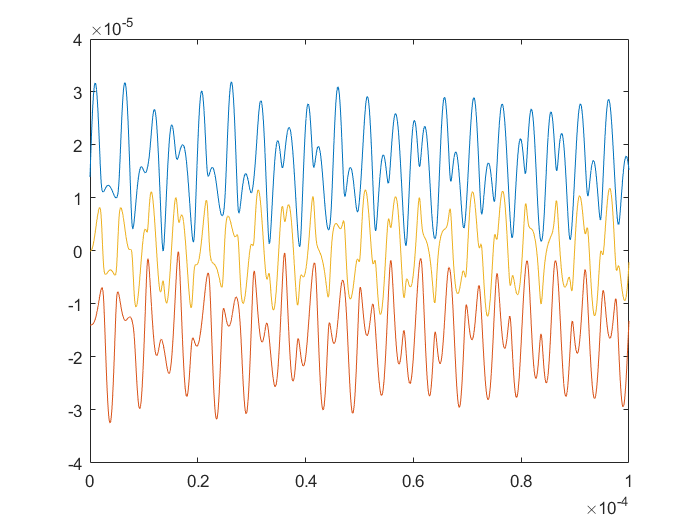

% % 2ions in 3-D pseudopotential (line1 to line105)
% 
% % define parameters
% mp=1.67e-27;
% m1=40*mp;
% Q=1.6e-19;
% epsilon=8.854e-12;
% 
% q0=0.3034;
% kq=Q^2/(4*pi*epsilon);
% w1=2*pi*5e6;
% w2=2*pi*0.2e6;
% k1=m1*w1^2;
% k2=m1*w2^2;
% omega=2*sqrt(2)*w1/q0;
% 
% 
% % time scale
% tau=1e-9;
% N=1e5;
% T=N*tau;
% 
% % initial parameters
% 
% l2=(Q^2/(2*m1*w2^2*pi*epsilon))^(1/3);
% r10=[0,0,l2/2];
% r20=-r10;
% v10=[10,20,10];
% v20=[0,0,0];
% % k=10;
% % kq=500;
% r=zeros(N,2,3);
% v=zeros(N,2,3);
% t=zeros(1,N);
% d=zeros(1,N);
% E=zeros(1,N);
% % r=[];
% % v=[];
% % t=[];
% % d=[];
% a=[];
% t(1)=0;
% % format x(time,order of the particle,spacial dimension)
% 
% % calculation
% r(1,1,:)=r10;
% r(1,2,:)=r20;
% v(1,1,:)=v10;
% v(1,2,:)=v20;
% d(1)=sqrt((r(1,1,1)-r(1,2,1))^2+(r(1,1,2)-r(1,2,2))^2+(r(1,1,3)-r(1,2,3))^2);
% E(1)=m1/2*(v(1,1,1)^2+v(1,1,2)^2+v(1,1,3)^2+v(1,2,1)^2+v(1,2,2)^2+v(1,2,3)^2)+...
%     k1/2*(r(1,1,1)^2+r(1,2,1)^2+r(1,1,2)^2+r(1,2,2)^2)+k2/2*(r(1,1,3)^2+r(1,2,3)^2)+...
%     kq*(1/d(1));
% 
% for i=2:N
%     t(i)=t(i-1)+tau;
%     d(i)=sqrt((r(i-1,1,1)-r(i-1,2,1))^2+(r(i-1,1,2)-r(i-1,2,2))^2+(r(i-1,1,3)-r(i-1,2,3))^2);
% %     a(1,1,:)=-k*r(i,1,:)+kq*(r(i,1,:)-r(i,2,:))/(d(i))^3;
% %     a(1,2,:)=-k*r(i,2,:)+kq*(r(i,2,:)-r(i,1,:))/(d(i))^3;
%     a(1,1,1)=(-(w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,1,1)+kq/m1*(r(i-1,1,1)-r(i-1,2,1))/(d(i))^3;
%     a(1,1,2)=((w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,1,2)+kq/m1*(r(i-1,1,2)-r(i-1,2,2))/(d(i))^3;
%     a(1,1,3)=-w2^2*r(i-1,1,3)+kq/m1*(r(i-1,1,3)-r(i-1,2,3))/(d(i))^3;
%     a(1,2,1)=(-(w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,2,1)+kq/m1*(r(i-1,2,1)-r(i-1,1,1))/(d(i))^3;
%     a(1,2,2)=((w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,2,2)+kq/m1*(r(i-1,2,2)-r(i-1,1,2))/(d(i))^3;
%     a(1,2,3)=-w2^2*r(i-1,2,3)+kq/m1*(r(i-1,2,3)-r(i-1,1,3))/(d(i))^3;
%     v(i,:,:)=v(i-1,:,:)+a*tau;
%     r(i,:,:)=r(i-1,:,:)+(v(i,:,:)+v(i,:,:))*tau/2;
%     E(i)=m1/2*(v(i,1,1)^2+v(i,1,2)^2+v(i,1,3)^2+v(i,2,1)^2+v(i,2,2)^2+v(i,2,3)^2)+...
%     k1/2*(r(i,1,1)^2+r(i,1,2)^2+r(i,2,1)^2+r(i,2,2)^2)+k2/2*(r(i,1,3)^2+r(i,2,3)^2)+...
%     kq*(1/d(i));
% end
% 
% % plot(t,r(:,1,1));
% % plot(t,r(:,1,2));
% % plot(t,r(:,1,3));
% % % hold on;
% % plot(t,r(:,2,1));
% % plot(t,r(:,2,2));
% % plot(t,r(:,2,3));
% 
% plot(t,r(:,1,3));
% hold on;
% plot(t,r(:,2,3));
% hold off;
% 
% % plot(r(:,1,1),r(:,1,2));
% % hold on;
% % plot(r(:,2,1),r(:,2,2));
% % hold off;
% plot(t,E);
% 
% plot(t,r(:,1,1));
% hold on
% plot(t,r(:,2,1));
% hold off
% 
% % plot(t,r(:,2,1));
% % hold on;
% % plot(t,r(:,1,1));
% % hold off;
% 
% plot3(r(:,1,1),r(:,1,2),r(:,1,3));
% hold on
% plot3(r(:,2,1),r(:,2,2),r(:,2,3));
% hold off





% 3ions in 3-D pseudopotential(line111 to line217)

% define parameters
mp=1.67e-27;
m1=40*mp;
Q=1.6e-19;
epsilon=8.854e-12;

q0=0.3034;
kq=Q^2/(4*pi*epsilon);
w1=2*pi*5e6;
w2=2*pi*0.2e6;
k1=m1*w1^2;
k2=m1*w2^2;
omega=2*sqrt(2)*w1/q0;


% time scale
tau=1e-9;
N=1e5;
T=N*tau;

% initial parameters
l=(5*Q*Q/(16*m1*w2^2*pi*epsilon))^(1/3);
r10=[0,0,l];
r20=-r10;
r30=[0,0,0];
v10=[10,30,30];
v20=[0,0,0];
v30=[0,0,0];
r=zeros(N,3,3);
v=zeros(N,3,3);
t=zeros(1,N);
d12=zeros(1,N);
d23=zeros(1,N);
d31=zeros(1,N);
E=zeros(1,N);
% r=[];
% v=[];
% t=[];
% d=[];
% a=[];
% t(1)=0;
% format x(time,order of the particle,spacial dimension)

% calculation
r(1,1,:)=r10;
r(1,2,:)=r20;
r(1,3,:)=r30;
v(1,1,:)=v10;
v(1,2,:)=v20;
v(1,3,:)=v30;
d12(1)=sqrt((r(1,1,1)-r(1,2,1))^2+(r(1,1,2)-r(1,2,2))^2+(r(1,1,3)-r(1,2,3))^2);
d23(1)=sqrt((r(1,2,1)-r(1,3,1))^2+(r(1,2,2)-r(1,3,2))^2+(r(1,2,3)-r(1,3,3))^2);
d31(1)=sqrt((r(1,1,1)-r(1,3,1))^2+(r(1,1,2)-r(1,3,2))^2+(r(1,1,3)-r(1,3,3))^2);


E(1)=m1/2*(v(1,1,1)^2+v(1,1,2)^2+v(1,1,3)^2+v(1,2,1)^2+v(1,2,2)^2+v(1,2,3)^2+v(1,3,1)^2+v(1,3,2)^2+v(1,3,3)^2)+...
    k1/2*(r(1,1,1)^2+r(1,2,1)^2+r(1,3,1)^2+r(1,1,2)^2+r(1,2,2)^2+r(1,3,2)^2)+k2/2*(r(1,1,3)^2+r(1,2,3)^2+r(1,3,3)^2)+...
    kq*(1/d12(1)+1/d23(1)+1/d31(1));

for i=2:N
    t(i)=t(i-1)+tau;
    d12(i)=sqrt((r(i-1,1,1)-r(i-1,2,1))^2+(r(i-1,1,2)-r(i-1,2,2))^2+(r(i-1,1,3)-r(i-1,2,3))^2);
    d23(i)=sqrt((r(i-1,2,1)-r(i-1,3,1))^2+(r(i-1,2,2)-r(i-1,3,2))^2+(r(i-1,2,3)-r(i-1,3,3))^2);
    d31(i)=sqrt((r(i-1,1,1)-r(i-1,3,1))^2+(r(i-1,1,2)-r(i-1,3,2))^2+(r(i-1,1,3)-r(i-1,3,3))^2);
    a(1,1,1)=(-(w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,1,1)+kq/m1*((r(i-1,1,1)-r(i-1,2,1))/(d12(i))^3+(r(i-1,1,1)-r(i-1,3,1))/(d31(i))^3);
    a(1,1,2)=((w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,1,2)+kq/m1*((r(i-1,1,2)-r(i-1,2,2))/(d12(i))^3+(r(i-1,1,2)-r(i-1,3,2))/(d31(i))^3);
    a(1,1,3)=-w2^2*r(i-1,1,3)+kq/m1*((r(i-1,1,3)-r(i-1,2,3))/(d12(i))^3+(r(i-1,1,3)-r(i-1,3,3))/(d31(i))^3);
    a(1,2,1)=(-(w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,2,1)+kq/m1*((r(i-1,2,1)-r(i-1,1,1))/(d12(i))^3+(r(i-1,2,1)-r(i-1,3,1))/(d23(i))^3);
    a(1,2,2)=((w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,2,2)+kq/m1*((r(i-1,2,2)-r(i-1,1,2))/(d12(i))^3+(r(i-1,2,2)-r(i-1,3,2))/(d23(i))^3);
    a(1,2,3)=-w2^2*r(i-1,2,3)+kq/m1*((r(i-1,2,3)-r(i-1,1,3))/(d12(i))^3+(r(i-1,2,3)-r(i-1,3,3))/(d23(i))^3);
    a(1,3,1)=(-(w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,3,1)+kq/m1*((r(i-1,3,1)-r(i-1,2,1))/(d23(i))^3+(r(i-1,3,1)-r(i-1,1,1))/(d31(i))^3);
    a(1,3,2)=((w1^2+w2^2/2)/(q0/4)*cos(omega*t(i-1))+w2^2/2)*r(i-1,3,2)+kq/m1*((r(i-1,3,2)-r(i-1,2,2))/(d23(i))^3+(r(i-1,3,2)-r(i-1,1,2))/(d31(i))^3);
    a(1,3,3)=-w2^2*r(i-1,3,3)+kq/m1*((r(i-1,3,3)-r(i-1,2,3))/(d23(i))^3+(r(i-1,3,3)-r(i-1,1,3))/(d31(i))^3);
    v(i,:,:)=v(i-1,:,:)+tau*a;
    r(i,:,:)=r(i-1,:,:)+(v(i,:,:)+v(i,:,:))*tau/2;
    E(i)=m1/2*(v(i,1,1)^2+v(i,1,2)^2+v(i,1,3)^2+v(i,2,1)^2+v(i,2,2)^2+v(i,2,3)^2+v(i,3,1)^2+v(i,3,2)^2+v(i,3,3)^2)+...
    k1/2*(r(i,1,1)^2+r(i,2,1)^2+r(i,3,1)^2+r(i,1,2)^2+r(i,2,2)^2+r(i,3,2)^2)+k2/2*(r(i,1,3)^2+r(i,2,3)^2+r(i,3,3)^2)+...
    kq*(1/d12(i)+1/d23(i)+1/d31(i));
end

% plot(t,r(:,1,1));
% plot(t,r(:,1,2));
% plot(t,r(:,1,3));
% % hold on;
% plot(t,r(:,2,1));
% plot(t,r(:,2,2));
% plot(t,r(:,2,3));

plot(t,r(:,1,3));
hold on;
plot(t,r(:,2,3));
plot(t,r(:,3,3));
hold off;

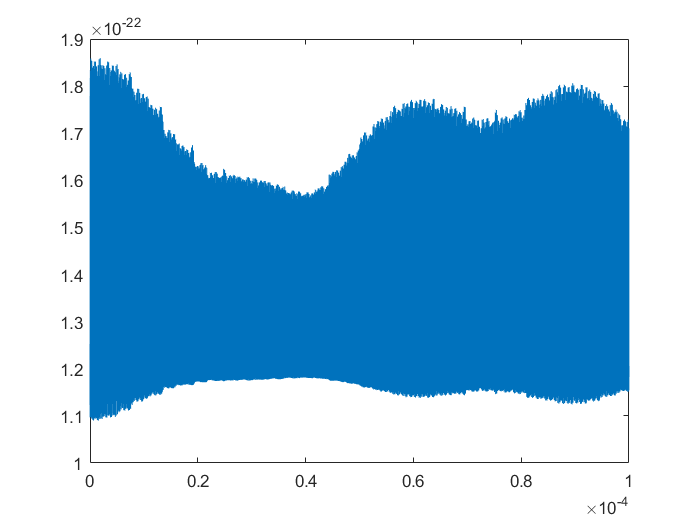


% plot(r(:,1,1),r(:,1,2));
% hold on;
% plot(r(:,2,1),r(:,2,2));
% hold off;
plot(t,E);

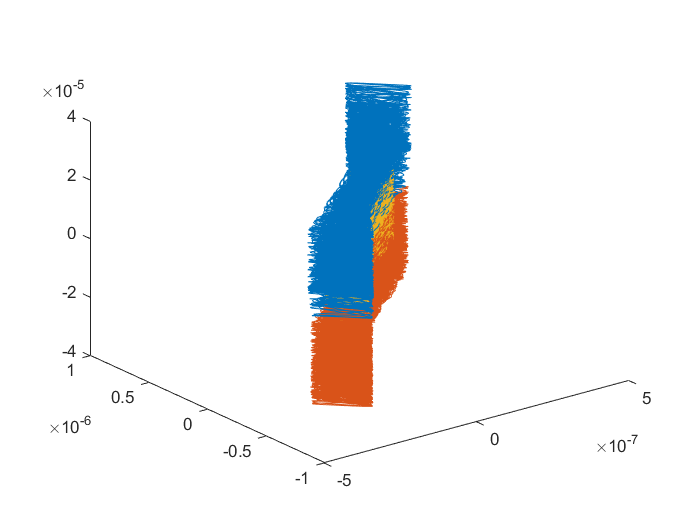


plot3(r(:,1,1),r(:,1,2),r(:,1,3));
hold on
plot3(r(:,2,1),r(:,2,2),r(:,2,3));
plot3(r(:,3,1),r(:,3,2),r(:,3,3));
hold off

% plot(t,r(:,1,1));
% hold on
% plot(t,r(:,2,1));
% hold off
% 
% plot(t,r(:,2,1));
% hold on;
% plot(t,r(:,1,1));
% hold off;

